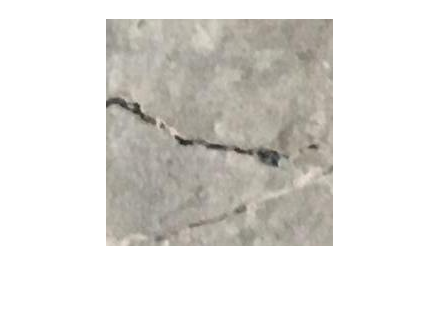

imgcrack = imread("Data/Concrete Crack Images/00035.jpg");
imshow(imgcrack);   

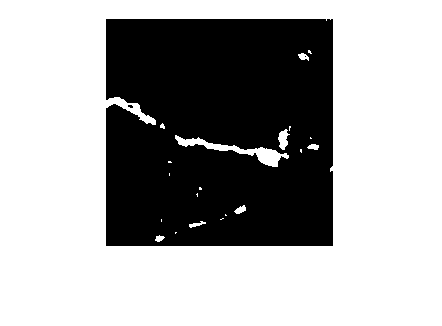


imgray = im2gray(imgcrack);
BW = imbinarize(imgray);
BW = ~BW;
imshow(BW);


ctr = sum(BW(:) == 1);
ctr

ctr = 1800

imgcrack = imread("Data/Concrete Crack Images/00035.jpg");
imshow(imgcrack);   

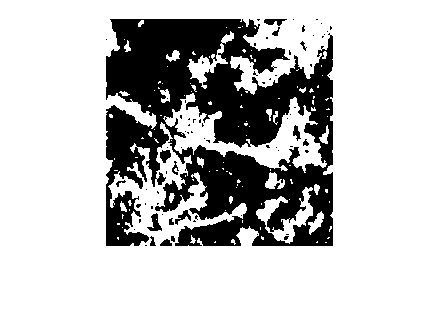


imgray = im2gray(imgcrack);
adj = imadjust(imgray);
BW = imbinarize(adj);
BW = ~BW;
imshow(BW);


ctr = sum(BW(:) == 1);
ctr

ctr = 17751

imgcrack = imread("Data/Concrete Crack Images/00035.jpg");
imshow(imgcrack);   

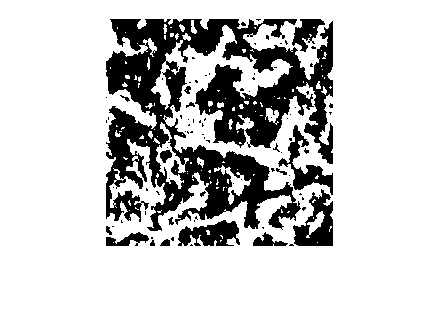


imgray = im2gray(imgcrack);
adj = adapthisteq(imgray);
BW = imbinarize(adj);
BW = ~BW;
imshow(BW);


ctr = sum(BW(:) == 1);
ctr

ctr = 22638

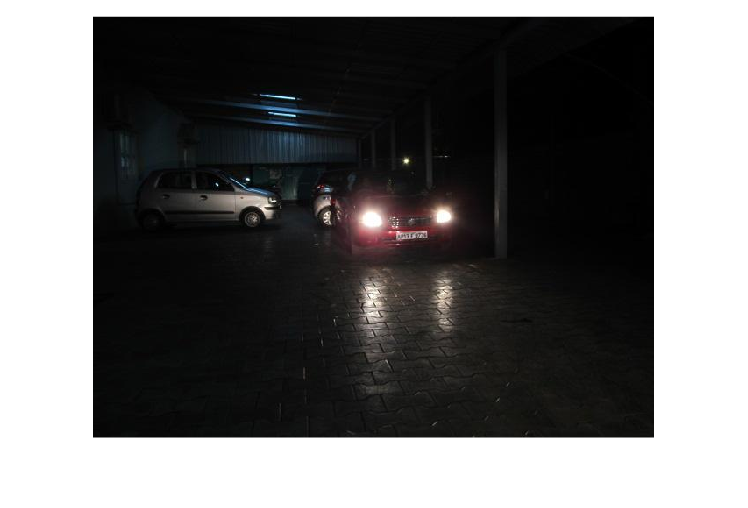

imgcar = imread("car_3.jpg");

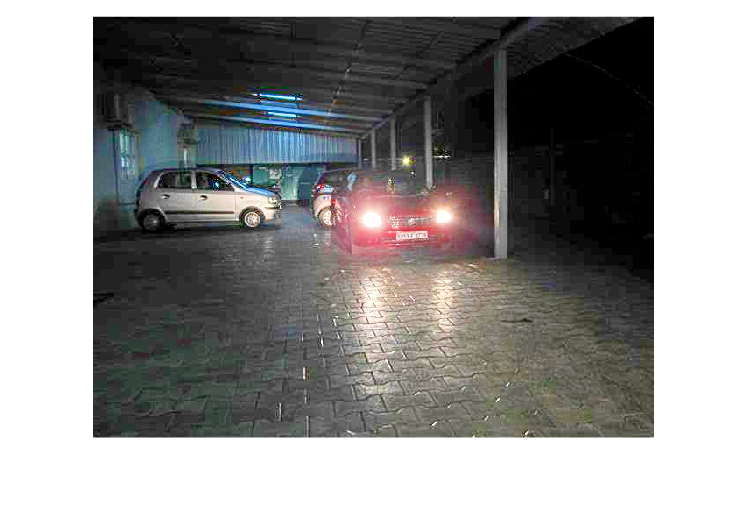

imshow(imgcar);

imgbrighten = imlocalbrighten(imgcar);
imshow(imgbrighten);

mean2(rgb2gray(imgbrighten))-mean2(rgb2gray(imgcar))

ans = 55.5325

imgcar = imread("car_3.jpg");
imshow(imgcar);

mean1 = mean2(rgb2gray(imgcar))

mean1 = 18.7302

imghsv = rgb2hsv(imgcar);
eqimg = histeq(imghsv);
equnit8 = uint8(hsv2rgb(eqimg));
meansec = mean2(rgb2gray(equnit8))

meansec = 0.2749

mean1-meansec

ans = 18.4553

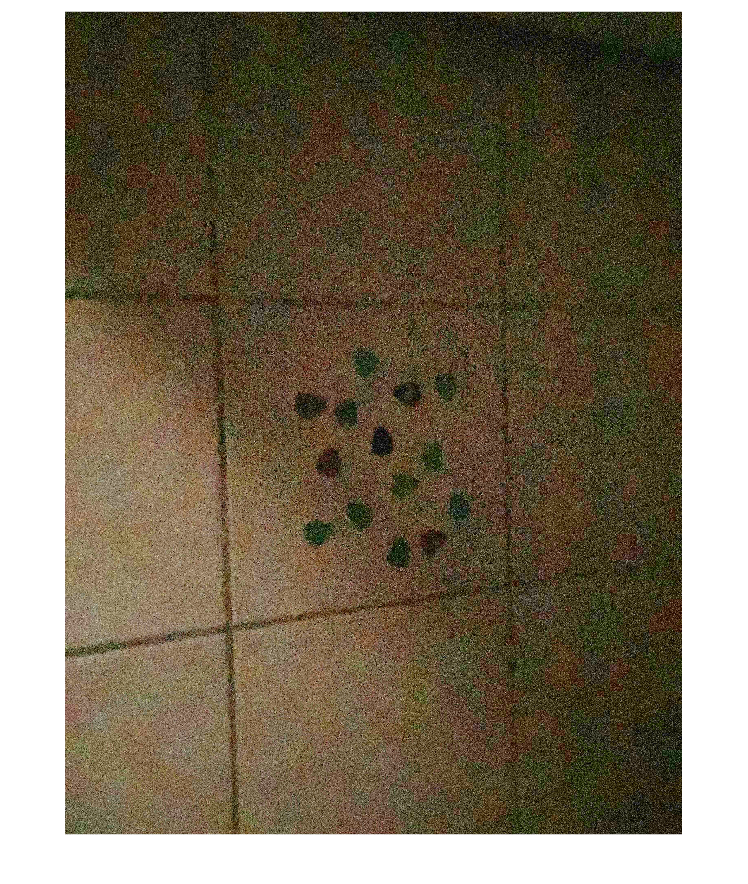

imgcar = imread("Data/MathWorks Images/picks.jpg");
imgbrighten = imlocalbrighten(imgcar);
imshow(imgbrighten);

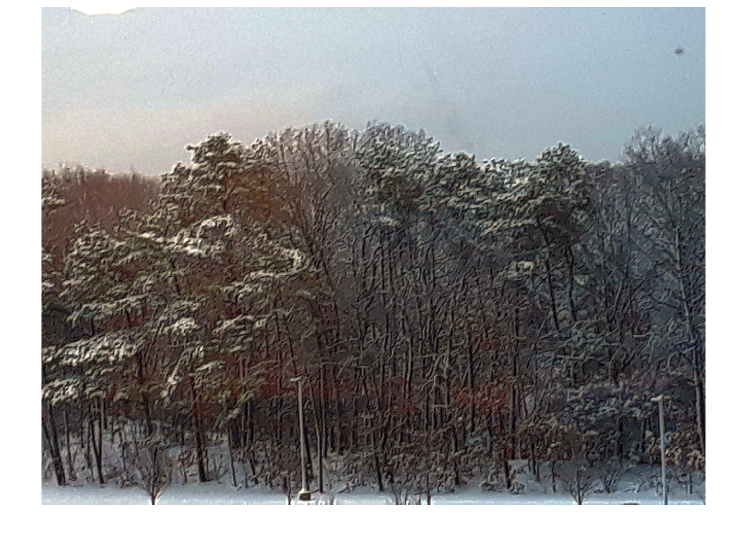

imgmount = imread("Data/MathWorks Images/mountain2.jpg");
imhazered = imreducehaze(imgmount);
imshow(imhazered)

mean_hz1 = mean2(rgb2gray(imgmount));
mean_hz2 = mean2(rgb2gray(imhazered));
mean_hz1-mean_hz2

ans = 46.0584

refImg = im2gray(imread("DATA/Concrete Crack Images/00004.jpg"));
newImg = im2gray(imread("Data/Concrete Crack Images/00143.jpg"));

refImgBW = graythresh(refImg)

refImgBW = 0.4510

newImgBW = imbinarize(newImg,refImgBW);

matchImg = imhistmatch(newImgBW, refImg);
matchImgBW = imbinarize(matchImg,refImgBW);